close all; 
clc;

%% Generate Training Data
x = 0.1 : 1/22 : 1;
y = (1 + 0.6 * sin(2*pi*x / 0.7) + 0.3 * sin(2*pi*x)) / 2;

figure('Position',[100 100 1200 400]);
subplot(1,3,1);
plot(x, y, 'bo-', 'LineWidth', 1.5); grid on;
xlabel('x'); ylabel('y'); title('Training Data');

%% RBF Parameters - Initial values (will be updated during training)
c1 = 0.2; c2 = 0.9; 
r1 = 0.22; r2 = 0.22;
w1 = rand(); w2 = rand(); b = rand();

eta_w = 0.01;    % Learning rate for weights/bias
eta_c = 0.005;   % Learning rate for centers (smaller for stability)
eta_r = 0.005;   % Learning rate for radii (smaller for stability)
r_min = 0.05;    % Minimum radius constraint
max_epochs = 10000;
threshold = 1e-6;

mse_history = zeros(max_epochs,1);

%% Training Loop - Update ALL parameters (centers, radii, weights)
for epoch = 1:max_epochs
    err_sum = 0;
    
    for i = 1:length(x)
        % Forward pass
        phi1 = exp(-(x(i)-c1)^2 / (2*r1^2));
        phi2 = exp(-(x(i)-c2)^2 / (2*r2^2));
        y_out = w1*phi1 + w2*phi2 + b;
        e = y(i) - y_out;
        err_sum = err_sum + e^2;
        
        % Update weights and bias
        w1 = w1 + eta_w * e * phi1;
        w2 = w2 + eta_w * e * phi2;
        b = b + eta_w * e;
        
        % Update centers c1, c2
        dc1 = eta_c * e * w1 * phi1 * (x(i) - c1) / (r1^2);
        dc2 = eta_c * e * w2 * phi2 * (x(i) - c2) / (r2^2);
        c1 = c1 + dc1;
        c2 = c2 + dc2;
        
        % Update radii r1, r2
        dr1 = eta_r * e * w1 * phi1 * (x(i) - c1)^2 / (r1^3);
        dr2 = eta_r * e * w2 * phi2 * (x(i) - c2)^2 / (r2^3);
        r1 = r1 + dr1; r1 = max(r1, r_min);
        r2 = r2 + dr2; r2 = max(r2, r_min);
    end
    
    mse = err_sum / length(x);
    mse_history(epoch) = mse;
    
    if mse < threshold
        mse_history = mse_history(1:epoch);
        fprintf('Converged at epoch %d, MSE = %.2e\n', epoch, mse);
        break;
    end
end

%% Plot Training Error
subplot(1,3,2);
plot(1:length(mse_history), mse_history, 'b-', 'LineWidth',2);
xlabel('Epoch'); ylabel('MSE'); grid on;
title('Training Error (All Parameters Updated)');

%% Final centers and radii
fprintf('Final c1=%.3f, r1=%.3f, c2=%.3f, r2=%.3f\n', c1, r1, c2, r2);

Final c1=0.191, r1=0.179, c2=0.904, r2=0.180


fprintf('Final w1=%.3f, w2=%.3f, b=%.3f\n', w1, w2, b);

Final w1=1.027, w2=0.796, b=-0.085


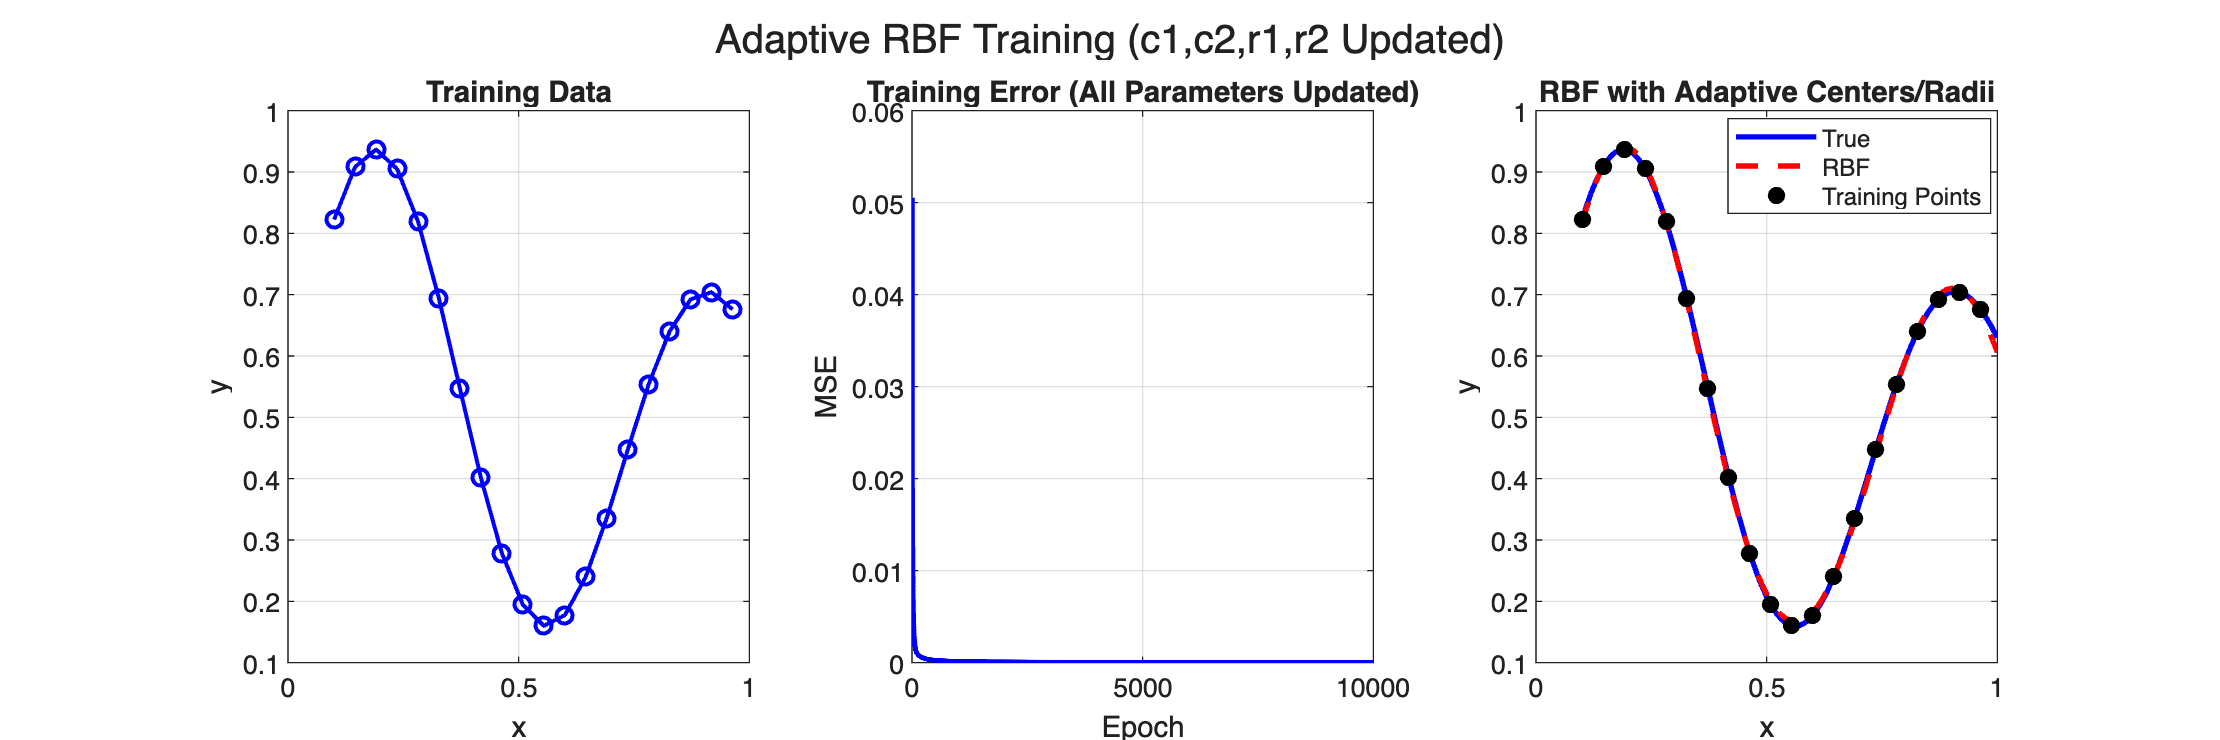


%% Fine Grid Testing
x_test = 0.1:0.01:1;
y_true = (1 + 0.6*sin(2*pi*x_test/0.7) + 0.3*sin(2*pi*x_test))/2;

y_test = zeros(size(x_test));
for i = 1:length(x_test)
    phi1 = exp(-(x_test(i)-c1)^2 / (2*r1^2));
    phi2 = exp(-(x_test(i)-c2)^2 / (2*r2^2));
    y_test(i) = w1*phi1 + w2*phi2 + b;
end

%% Final Plot
subplot(1,3,3);
plot(x_test, y_true, 'b-', 'LineWidth',2); hold on;
plot(x_test, y_test, 'r--', 'LineWidth',2);
plot(x, y, 'ko','MarkerFaceColor','k','MarkerSize',6);
xlabel('x'); ylabel('y'); grid on;
title('RBF with Adaptive Centers/Radii');
legend('True','RBF','Training Points','Location','best');

sgtitle('Adaptive RBF Training (c1,c2,r1,r2 Updated)');

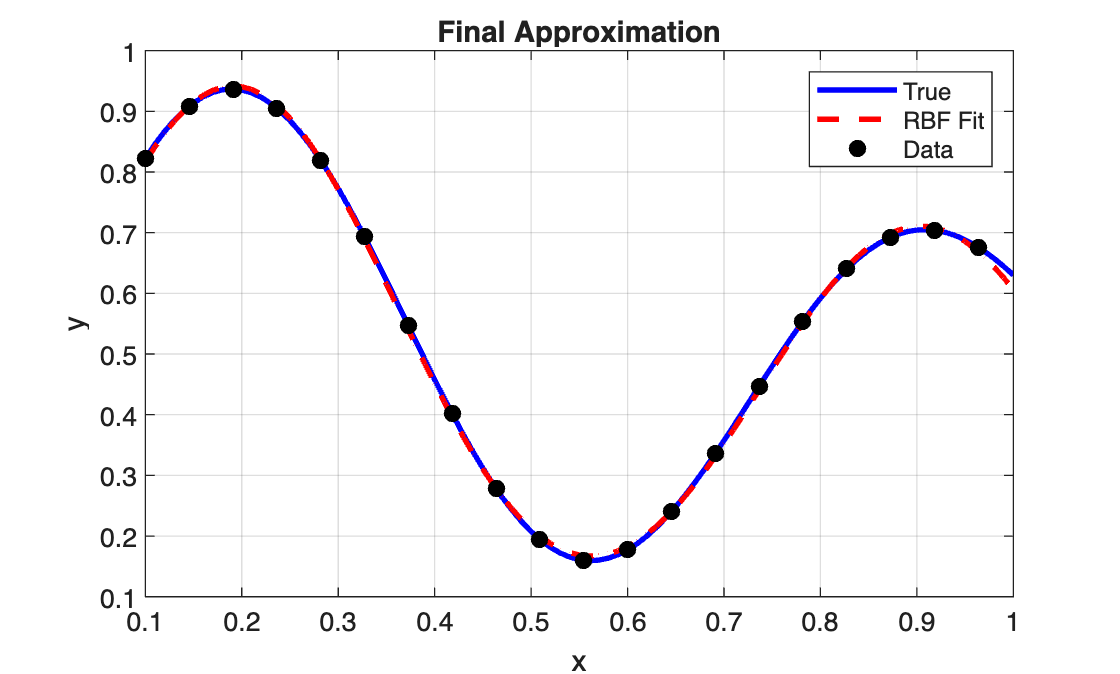


%% Additional visualization: RBF basis functions
figure;
plot(x_test, y_true, 'b-', 'LineWidth',2); hold on;
plot(x_test, y_test, 'r--', 'LineWidth',2);
plot(x, y, 'ko','MarkerFaceColor','k');
xlabel('x'); ylabel('y'); grid on; legend('True','RBF Fit','Data');
title('Final Approximation');